clear all
d1=load("E:\MTP2\ndvi_2010_2018_mat.mat");
nd=d1.NDVI;

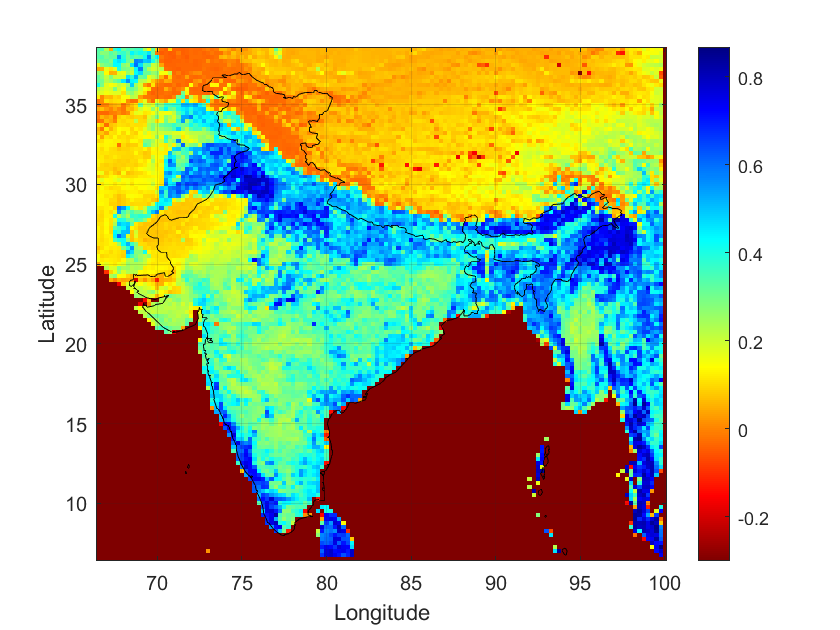

data=nd(:,:,3);
lat=data(2:130,1,1);
lon=data(1,2:136,1)';
crop1=(data(2:130,2:136,1));
%cropf_slope=fliplr(flipud(crop1));
%J(2:130,2:136,1)=fliplr(flipud(crop1));
%slp=pcolor(lon,lat,flipud(cropf_slope));
slp=imagesc(lon,lat,crop1);
set(gca,'YDir','normal')
%slp.EdgeColor='none';
xlabel('Longitude'); % Labelling x axis 
ylabel('Latitude'); % Labelling y axis
%title(' slope values for SPI and SIF Z-score (1 month lag)'); % Putting title to the figure
colormap(flipud(jet)) % Setting a color scheme
hcb1=colorbar; % Showing the scheme on a scale
%caxis([-0.5 0.5])
%title(hcb1,'(in m3/m3)') % Titling a colorbar
grid on % Showing grid lines
hold on % Starting a new plot on same figure retaining the former
geoshow("E:\MTP2\precipitation\shapefile\india.shp",'FaceAlpha',0); % Plotting shapefile of India - you should have a .shp shapefile